% small signal data


## Run

Tend = 10

Tend = 10

% simOut = sim("simli", "StopTime", "Tend");
simBig = sim("DQ\martins_version_wconv_wdc.slx","StopTime", "50");

## Simulation output


struc_v_t_dq= simOut.v_t_small;
struc_v_vsc_dq= simOut.vi_dq_vsc;

struc_powers = simOut.PQ_grid_small;
struc_vsm = simOut.VSM_small;
struc_dc_link = simOut.DC_link_small;
struc_qdroop = simOut.Qdroop_small;
t_simout = simOut.tout;

        

## extract data to arrays

t_dc_link = struc_dc_link.time;
DC_voltage = struc_dc_link.signals(1).values;
DC_power_link = struc_dc_link.signals(2).values(:,1);
DC_power_grid = struc_dc_link.signals(2).values(:,2);

v_D_t_vec = struc_v_t_dq.signals(1).values(:,1);
v_Q_t_vec = struc_v_t_dq.signals(1).values(:,2);
v_d_vsc_vec = struc_v_vsc_dq.signals(1).values(:,1);
v_q_vsc_vec = struc_v_vsc_dq.signals(1).values(:,2);

P_vsc = struc_powers.signals(1).values;
Q_vsc = struc_powers.signals(2).values;

VSM_P_Delta = struc_vsm.signals(1).values;
VSM_freq = struc_vsm.signals(2).values;
VSM_theta_deg = struc_vsm.signals(3).values;

% big signal 
struc_v_t_dq= simBig.v_t_wdc_big;
struc_v_vsc_dq= simBig.vi_dq_vsc_big;

struc_powers = simBig.PQ_grid_wdc_big;
struc_vsm = simBig.VSM_wdc_big;
struc_dc_link = simBig.DC_link_big;
struc_qdroop = simBig.Qdroop_wdc_big;


## extract data to arrays

t_dc_link_big = struc_dc_link.time-40;
DC_voltage_big = struc_dc_link.signals(1).values;
DC_power_link_big = struc_dc_link.signals(2).values(:,1);
DC_power_grid_big = struc_dc_link.signals(2).values(:,2);

v_D_t_vec_big = struc_v_t_dq.signals(1).values(:,1);
v_Q_t_vec_big = struc_v_t_dq.signals(1).values(:,2);
v_d_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,1);
v_q_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,2);
P_vsc_big = struc_powers.signals(1).values;
Q_vsc_big = struc_powers.signals(2).values;

VSM_P_Delta_big = struc_vsm.signals(1).values;
VSM_freq_big = struc_vsm.signals(2).values;
VSM_theta_deg_big = struc_vsm.signals(3).values;

## plotting

plotTitle = "Phaseshift"

plotTitle = "Phaseshift"

figName = plotTitle;


## VSM

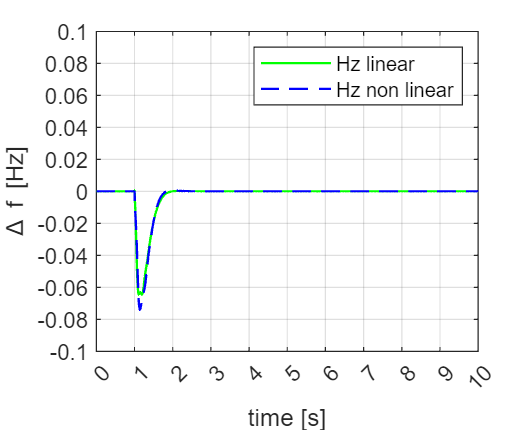

figure('Name','VSM'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t_dc_link,VSM_freq,'g-',LineWidth=1);
plot(t_dc_link_big,VSM_freq_big,'b--',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([0 Tend -0.1 0.1])
legend('Hz linear', 'Hz non linear') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('\Delta f [Hz]')
ay = gca;
ay.YTick = -0.2:0.02:0.2;
ay.XTick =0:1:Tend;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "vsm"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "vsm"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

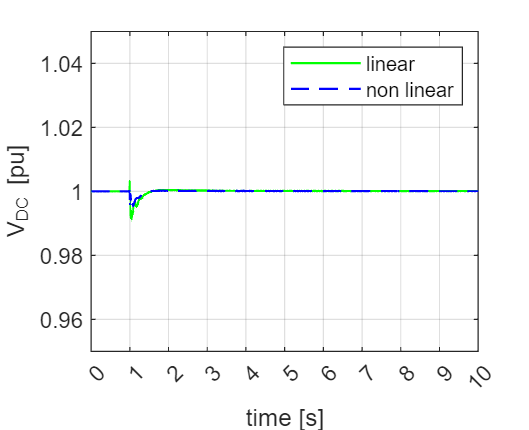

%% DC link
figure('Name','DClinkv'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t_dc_link,DC_voltage+1,'g-',LineWidth=1);
plot(t_dc_link_big,DC_voltage_big,'b--',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([0 Tend 0.95 1.05])
legend('linear', 'non linear') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('V_DC [pu]')
ay = gca;
ay.YTick = 0.94:0.02:1.06;
ay.XTick =0:1:Tend;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "DClinkv"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "DClinkv"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Terminal voltage link

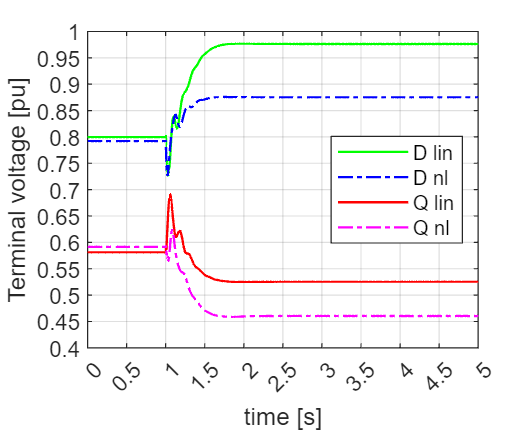


figure('Name','v_t'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t_dc_link,v_D_t_vec+v_D0_t,'g-',LineWidth=1);
plot(t_dc_link_big,v_D_t_vec_big,'b-.',LineWidth=1);
plot(t_dc_link,v_Q_t_vec+v_Q0_t,'r-',LineWidth=1);
plot(t_dc_link_big,v_Q_t_vec_big,'m-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([0 5 0.4 1])
legend('D lin', 'D nl', 'Q lin', 'Q nl',Location='east') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('Terminal voltage [pu]')
ay = gca;
ay.YTick = 0:0.05:5;
ay.XTick =0:0.5:5;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "v_t"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "v_t"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## vsc voltage

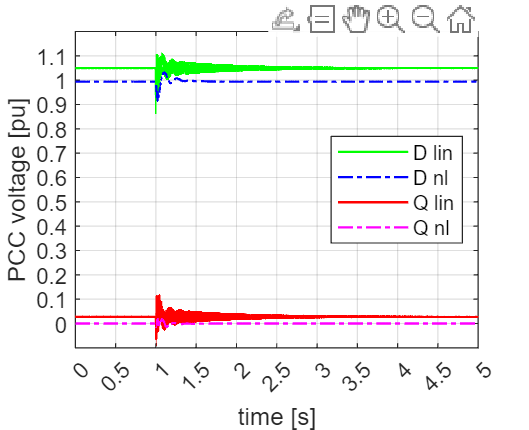


figure('Name','v_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t_dc_link,v_d_vsc_vec+v_dq_vsc0(1),'g-',LineWidth=1);
plot(t_dc_link_big,v_d_vsc_vec_big,'b-.',LineWidth=1);
plot(t_dc_link,v_q_vsc_vec+v_dq_vsc0(2),'r-',LineWidth=1);
plot(t_dc_link_big,v_q_vsc_vec_big,'m-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([0 5 -0.1 1.2])
legend('D lin', 'D nl', 'Q lin', 'Q nl',Location='east') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('PCC voltage [pu]')
ay = gca;
ay.YTick = 0:0.1:5;
ay.XTick =0:0.5:5;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "v_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "v_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

% ssA = linsys1.A;
% ss_statenames = linsys1.StateName;
% 
% % save("statespace\validation\dclink_ss_lin_ss.mat","ssA","ss_statenames",'-mat')